format shortg
clear all

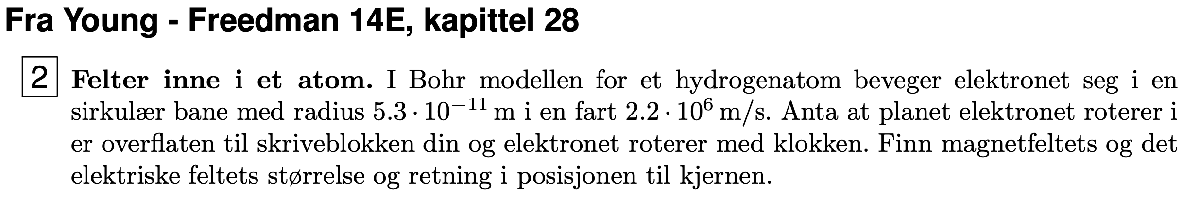

r = 5.3 * 10^-11; % meter
v = 2.2 * 10^6  ; % meter/sekund

Siden det negative elektronet beveger seg med klokken, går "strømmen" mot klokken, høyrehåndsregelene sier da at magnetfeltet sin retning i posisjonen til kjernen vil være opp av boken med en størrelse på:

B = MagnetfeltFraLadningIBevegelse(0, e, v, 90, r);
fprintf('Magnetfeltet er: %g T', signif(B, 2))

Magnetfeltet er: 13 T

Når elektroknet er i bevegelse endrer det retning hele tiden siden det går i en sirkelbevegelse, gjennomsnittlig elektrisk feltstyrke blir derfor $0\;N/C$

E = ElektriskFeltstyrkeFraPunktladning(0, e, r);
fprintf('Elektrisk feltstyrken når elektronet står stille: %g N/C', signif(E, 2))

Elektrisk feltstyrken når elektronet står stille: 5.1e+11 N/C

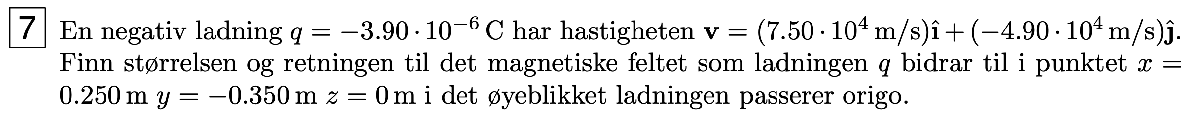

q = -3.90 * 10^-6; % C
v = [7.50*10^4 -4.90*10^4 0];
r = [0.250 -0.350 0];

bruker formelen: $B=\frac{u_0 }{4\pi }\frac{q*v_{\textrm{ij}} \times r_{\textrm{ij}} }{r^3 }$

[retning, styrke] = MagnetfeltFraLadningIBevegelseVektor(q, v, r);
fprintf('Magnetfeltet blir: %g Tk´', signif(styrke,3))

Magnetfeltet blir: -6.86e-08 Tk´

retningen til dette feltet blir:

disp(retning)

           0           0      -14000



Altså i negativ k-retning

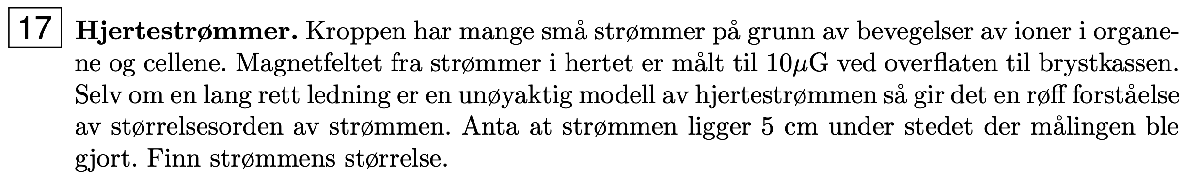

G = 10^-4; % T
B = 10*10^-6 * G; % T
r = 5 * 10^-2; % m


$$B=\frac{u_o I}{2\pi r}$$


I = MagnetfeltFraStrom(B, 0, r); % Ampere
fprintf('Strømmen blir: %g Ampere', signif(I, 1));

Strømmen blir: 0.0003 Ampere

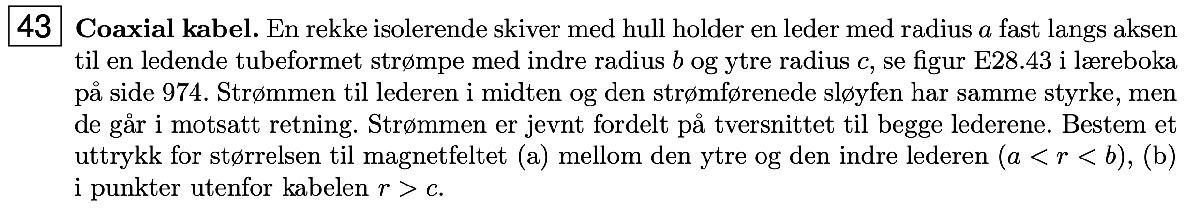

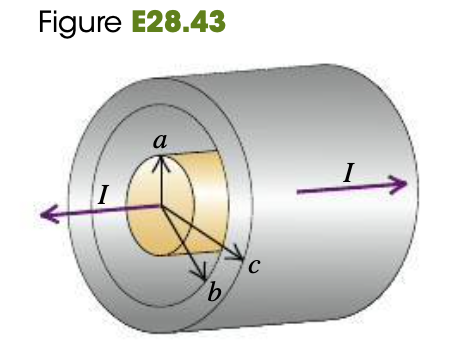

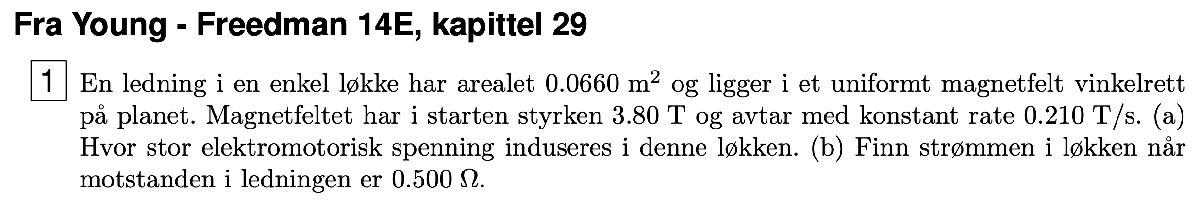

A = 0.0660; % m^2
B_start = 3.80; % T
B_rate = -0.210; % T/s

(a)


$$\varepsilon =\frac{d\Phi_B }{\mathrm{dt}}=\frac{A*B}{\mathrm{dt}}=A*\frac{B}{\mathrm{dt}}=A*B_{\mathrm{rate}}$$


e_b = A*abs(B_rate)

V =       0.01386


signif(e_b,3)

ans =        0.0139


(b)

R = 0.5; % Ohm
I = ohms_lov(e_b, R, 0);
signif(I , 3)

ans =        0.0277


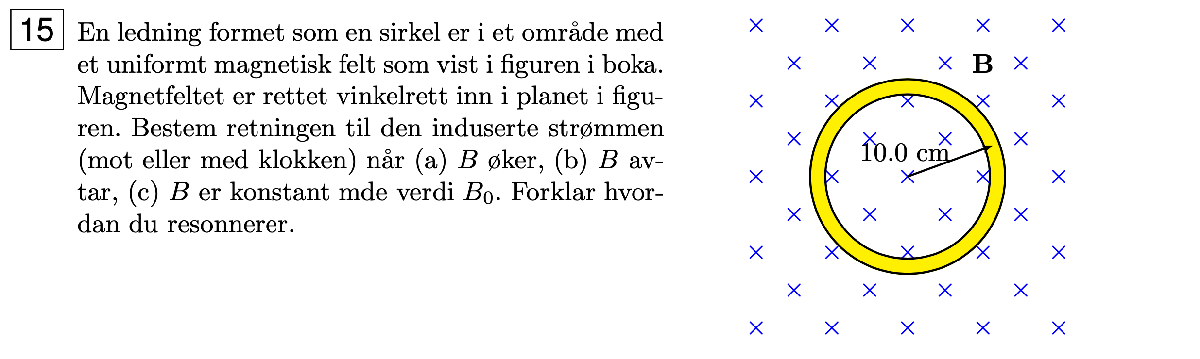

(a) Feltet øker nedover inne i spolen, det betyr at strømmen som blir indusert vil motvirke denne økningen ved å danne en strøm som oppretter et magnetfelt i motsatt retning:

Høyrehåndsregelen gir oss da at strømmen går mot klokken:

(b) av samme grunn som i (a), men nå minker B, altså "øker" feltet i retningen oppover. Så nå vil strømmen gå med klokken.

(c) da det ikke er noen endring i magnetfeltet induseres det ingen strøm i spolen.

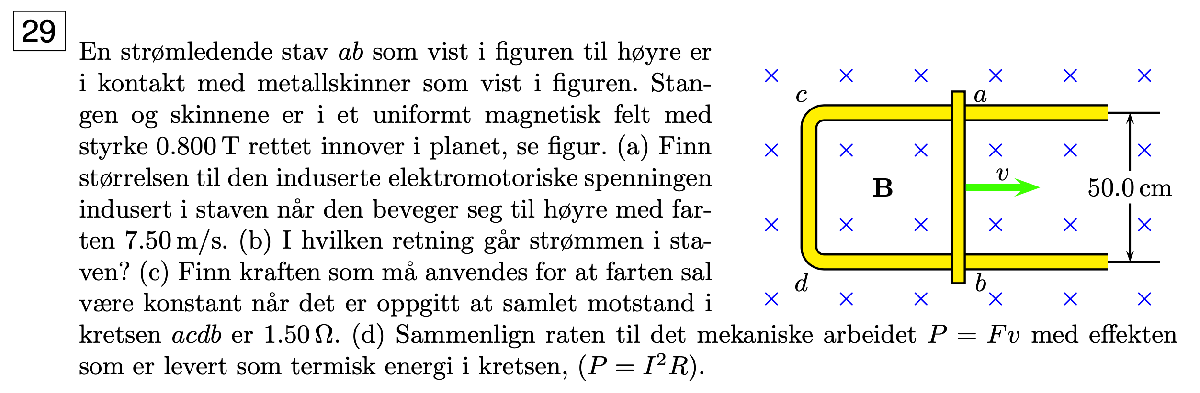

B = 0.800; % T
l = 50.0 * 10^-2; % m

(a)

v = 7.50; % m/s


$$\varepsilon =\frac{d\Phi_B }{\mathrm{dt}}=\frac{A*B}{\mathrm{dt}}=\frac{A}{\mathrm{dt}}*B$$


Finner først endringen i areal per tid:

A_dt = l * v; % m^2/s

Da får vi den induserte spenningen:

e_b = A_dt * B;
signif(e_b, 3)

ans =      3


(b)

Strømmen i staven vil motvirke retningen til feltet på innsiden, siden arealet øker, vil også feltet på innsiden øke i retning nedover. strømmen i staven vil da motvirke denne retningen med sitt eget magnetfelt og strømmen vil da gå Oppover (fra b til a)

(c)

R = 1.50; % Ohm

For å ha konstant fart må summen av krefter som virker på staven være 0:

Finner derfor først kraften som virker på staven fra magnetfeltet, denne kraften vil da være lik kraften som må anvendes for å holde konstant fart:

I = ohms_lov(e_b,R,0);
F = B * I * l % Newton

F =           0.8


(d)

P_Fv = F * v % Watt

P_Fv =      6


P_I2R = ElektriskEffekt(0,0,I, R) % Watt

P_I2R =      6


Vi ser at de to er like.

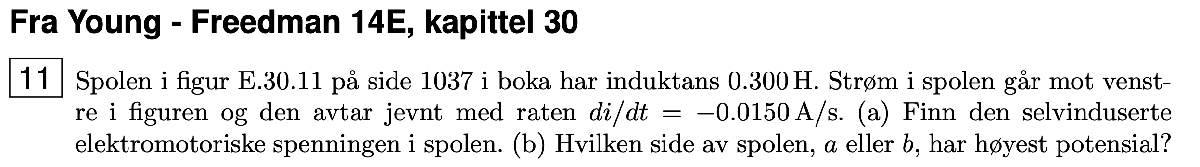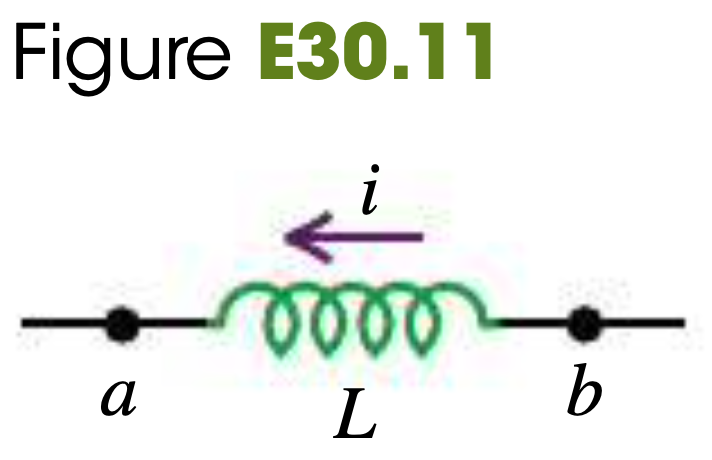

L = 0.300; % H
di_dt = -0.0150; % A/s

(a)


$$\varepsilon =\left|L*\frac{\mathrm{di}}{\mathrm{dt}}\right|$$


e_b = abs(L * di_dt)

e_b =        0.0045


(b)

"Current is decreasing from b to a. According to Lenz's law emf is induced such as to maintain current constant. i.e,induced voltage is such a way $v_a >v_b$"	

Det er to spenninger til stede i spolen. Den ene er fra kretsen og den andre er den elektromotoriske spenningen. De virker hver sin retning. Lenz lov sier at emf g ̊ar fra a til b. For  ̊a balansere ems-en m ̊a potensialet i kretsen g ̊a andre veien. 

Potensialet er altså høyest i $a$.�

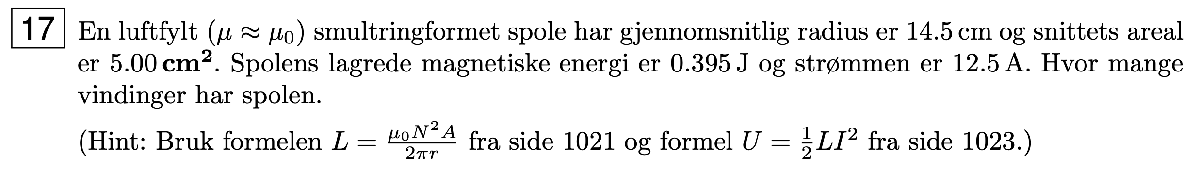

r = 14.5 * 10^-2; % m
A = 5.00 * 10^-4; % m
U = 0.395; % J
I = 12.5; % Ampere


$$\begin{array}{l}
U=\frac{1}{2}{\mathrm{LI}}^2 \Rightarrow L=\frac{2U}{I^2 }\\
\frac{2U}{I^2 }=\frac{u_0 N^2 A}{2\pi r}\Rightarrow N=\sqrt{\frac{4U\pi r}{I^2 u_0 A}}
\end{array}$$


N = sqrt(4*U*pi*r/(I^2*u_0*A));
signif(N, 3)

ans =         2710



$$N=\sqrt{\frac{2\pi r*L}{u_0 A}}$$


L = 2*U/I^2;
N = sqrt(2*pi*r*L/(u_0*A));
signif(N, 3)

ans =         2710


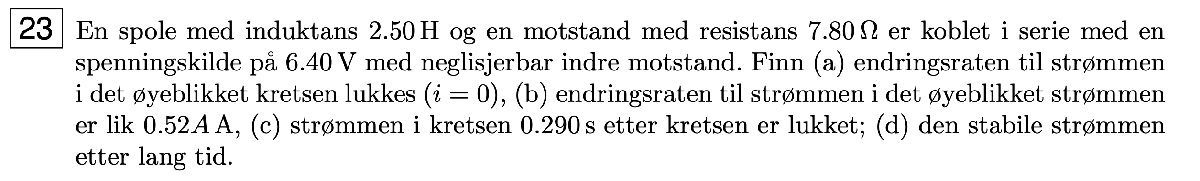

L = 2.50; % Henry
R = 7.80; % Ohm
e_b = 6.40; % Volt

(a)

i = 0;


$$\varepsilon i=i^2 R+\mathrm{Li}\;\frac{\mathrm{di}}{\mathrm{dt}}$$



$$\frac{\mathrm{di}}{\mathrm{dt}}=\frac{\varepsilon i-i^2 R}{\mathrm{Li}}=\frac{\varepsilon -\mathrm{iR}}{L}$$


endringsraten = (e_b-i*R)/L;
signif(endringsraten, 3)

ans =          2.56


(b)

i = 0.52; % A


$$U=\varepsilon -R*i$$


V = e_b - R * i;
endringsraten = (e_b-i*R)/L;
signif(endringsraten, 3)

ans =         0.938


(c)

t = 0.290; % s				

Kirkchhoffs 2. regel for kretsen gir $\varepsilon -\mathrm{Ri}-L\;\frac{\mathrm{di}}{\mathrm{dt}}$ og vi har at $i\left(0\right)=0$


$$i\left(t\right)=\frac{\varepsilon }{R}\left(1-e^{-\frac{R}{L}*t} \right)$$


i = @(t)e_b/R*(1-exp(-(R/L)*t));
signif(i(t), 3)

ans =         0.489


(d)

Etter lang tid vil spolen fungere som en vanlig ledning, vi har derfor kun en krets med en motsant og strømmen er gitt ved:

I = ohms_lov(e_b, R, 0);
signif(I, 3)

ans =         0.821
